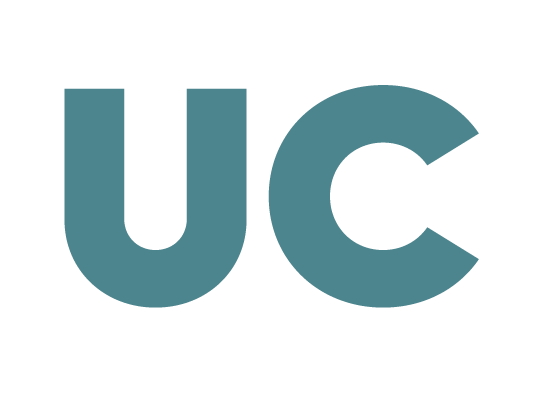

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Práctica 9: Mínimos cuadrados**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados

- Ajuste a una nube de puntos

## **Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados**

### Mínimos cuadrados utilizando la proyección ortogonal

Consideremos el siguiente sistema de ecuaciones lineales:


$$\textstyle\left\{  \begin{array}{rcr}
			 -x  + 4y & = & 15\\ 
			 y & = & 6\\
			 -y & = & 4\\  
			 x -2y & = & -5\\  
		 \end{array}\right.$$


Es fácil comprobar por el Teorema de Rouché Forbenius que es incompatible (no tiene solución):

A = [-1 4; 0 1; 0 -1; 1 -2];  % matriz de coeficientes
b = [15 6 4 -5]';             % vector de términos independientes
[rank(A) rank([A b])]         % S.I.

Hemos visto que en estas circunstancias siempre es posible obtener una solución aproximada por mínimos cuadrados. Se trataría de sustituir el vector de términos indpendientes $\vec{b}$, para el cual no existe solución, por otro vector $\hat{\vec{b}}$ para el cual el sistema sí tenga solución. Este vector $\hat{\vec{b}}$ será la proyección de $\vec{b}$ sobre el subespacio generado por las columnas de $A$ (subespacio columna $colA$).  A partir de la base del subespacio columna ($colA$) obtendremos la matriz de proyección que nos permitirá encontrar el vector $\hat{\vec{b}}$ para el cual el sistema pasa a ser compatible.

Hemos visto, que el cálculo de la matriz de proyección ortogonal se simplifica si usamos una base ortonormal del subespacio columna ($P_S=B_{So}B_{So}^t$). 

B_ortn=orth(A)
Ps = B_ortn * B_ortn'  % matriz de proyección 
bhat = Ps*b  % vector para el cual el sistema pasa a ser compatible. Es

Si comparamos el nuevo vector de términos independientes $\hat{\vec{b}}$ con el del sistema original vemos que no se parecen demasiado. Sin embargo el vector $\hat{\vec{b}}$ es el vector perteneciente al espacio columna lo más parecido posible a $\vec{b}$, es decir,   $\hat{\vec{b}}$ es el vector lo más próximo posible a $\vec{b}$ que nos permite obtener un sistema $A \vec{x}=\hat{\vec{b}}$ que sea compatible.  

Comprobemos que $A \vec{x}=\hat{\vec{b}}$ es ahora un sistema compatible.

[rank(A), rank([A bhat])]  % S.C.I.

Nuestro nuevo sistema (el que resulta de sustituir $\vec{b}$ por $\hat{\vec{b}}$) es compatible determinado, ya que las columnas de A son linealmente independientes, por lo que podemos hallar fácilmente su única solución mediante el operador "\"

xhat=A\bhat

Acabamos de ver que la solución de mínimos cuadrados es $x=-1, y=3$. Esto quiere decir que el vector $\hat{\vec{b}}$ se puede expresar como combinación lineal de las columnas de $A$, siendo los coeficientes de dicha C.L. $-1$ y $3$.

$\hat{\vec{x}}$ es la mejor aproximación que podemos encontrar para el sistema $A\vec{x}=\vec{b}$, aunque obviamente no es solución del sistema incompatible, como podemos comprobar

A*xhat-b  % distinto de 0

El error cuadrático cometido sería:

norm(bhat-b)^2  % error cuadrático 

### Uso de A\b para encontrar lasolución de mínimos cuadrados

**Recordatorio**: El operador A\b nos permitía resolver rápidamente un S.C.D. Sin embargo, recordemos que debíamos tener cuidado en su uso en S.C.I. (ya que nos devuelve una única solución de las infinitas posibles) y en S.I., ya que nos devuelve un vector que no es solución. ¡Este vector es justamente la solución particular de mínimos cuadrados!

Si intentamos resolver directamente un sistema incompatible mediante el operador "\" MATLAB nos devolverá la solución de mínimos cuadrados, pero es importante distinguir cuándo la solución es la verdadera y cuando es aproximada.

## **Ajuste a una nube de puntos**

Hemos visto que dada una nube de puntos, se puede ajustar por un tipo de función predefinida (por ejemplo una recta, un polinomio de grado 2, una exponencial, etc.). Para ello habría que resolver el sistema que resulte de forzar a que nuestra función aproximadora pase por todos los puntos de la nube. Previsiblemente, este sistema será incompatible (no tendrá solución). Sin embargo, podremos buscar una solución aproximada por mínimos cuadrados. A modo de ejemplo, imaginemos que tenemos los siguientes datos experimentales relativos a la relación entre potencia transmitida y potencia recibida en un canal de comunicación:

                                                

Para obtener un ajuste lineal (es decir, una recta $y=mx+n$), habría que resolver el sistema


$$\textstyle\left\{  \begin{array}{rcr}
			 2m  + n & = & 6\\ 
			 5m + n & = & 7.9\\
			 7m +n & = & 8.5\\  
		 \end{array}\right.$$


en el que las incógnitas serán $m$ y $n$ (coeficientes de la recta de ajuste). Lo resolvemos:

format short
x0 = [2 5 7];      % coordenada x de los puntos de la nube
y0 = [6 7.9 8.5];  % coordenada y de los puntos de la nube
A = [x0', ones(length(x0), 1)]  % matriz de coeficientes del sistema a resolver
b = y0'  % vector de términos independientes del sistema a resolver
[rank(A) rank([A b])]  % S.I.

Para resolver este sistema por el método de mínimos cuadrados, habrá que sustituir  el vector de términos independientes $\vec{b}$ por $\hat{\vec{b}}$, que corresponde con  la proyección de $\vec{b}$ sobre el subespacio generado por las columnas de $A$ (ColA). 

Calculamos $\hat{\vec{b}}$ utilizando la matriz de proyección sobre el subespacio ColA: 

Bortn=orth(A)
Ps = Bortn*Bortn'  % proyeción de b sobre subespacio ColA
bhat = Ps * b
[rank(A) rank([A bhat])]
sol_mc=A\bhat

El primer (segundo) elemento de esta solución será el coeficiente $m$ ($n$) de nuestro ajuste lineal. Por tanto, el polinomio aproximador buscado es $y=0.5105x+5.0842$.

Si en lugar de un polinomio aproximador de grado $1$ (una recta), quisiera uno de grado $2$ ( $y=mx^2+nx+p$), tendría que resolver el siguiente sistema:


$$\textstyle\left\{  \begin{array}{rcr}
			 2^2m  + 2n +p& = & 6\\ 
			 5^2m + 5n +p& = & 7.9\\
			 7^2m +7n +p& = & 8.5\\  
		 \end{array}\right.$$


Donde las incógnitas serán $m$, $n$ y $p$ (los coeficientes de la curva de ajuste). Lo resolvemos:

A = [x0.^2', x0', ones(length(x0), 1)]  % matriz de coeficientes (el 
% simbolo ".^" se utiliza para realizar la potenciación elemento a elemento)
b = y0'  % vector de términos independientes
[rank(A) rank([A b])]  % S.C.D.

Vemos que en este caso, el sistema es compatible determinado (existe solución exacta, y es única). Esto ocurre porque tenemos únicamente tres puntos, por lo que, el número de ecuaciones y el de incógnitas se igualan. *En general, si tenemos una nube con *$n$* puntos, siempre podremos encontrar un polinomio interpolador de grado *$n-1$* que pase por todos ellos.* En nuestro caso, el polinomio de segundo grado que buscamos vendrá dado por la solución (única y exacta) del sistema que hemos planteado:

sol = A\b  % S.C.D.

Es decir, el polinomio de grado 2 aproximador será $y=-0.0667x^2 + 1.1x + 4.0667$.